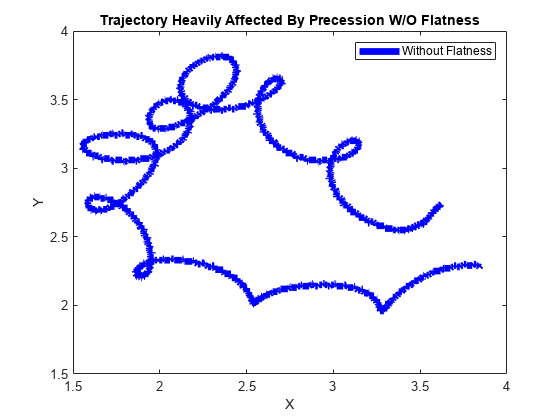

clear; % clears all var
clc; % clears command window
data_ref = load("ref_video.mat");
data_cw = load("cw_video.mat");
data_ccw = load("ccw_video.mat");
data = load("first_successful.mat");


x = (data.test(1:2900,1));
y = (data.test(1:2900,2));

x_cw = (data_cw.x_cw(1,:));
y_cw = (data_cw.x_cw(2,:));
z_cw = (data_cw.x_cw(3,:));

x_r = (data_ref.ref_x(1,:));
y_r = (data_ref.ref_x(2,:));
z_r = (data_ref.ref_x(3,:));

x_ccw = (data_ccw.x_g(1,:));
y_ccw = (data_ccw.x_g(2,:));
z_ccw = (data_ccw.x_g(3,:));

plot(x,y,'Color','blue','linewidth',5)
xlabel('X')
ylabel('Y')
legend('Without Flatness')
title('Trajectory Heavily Affected By Precession W/O Flatness')

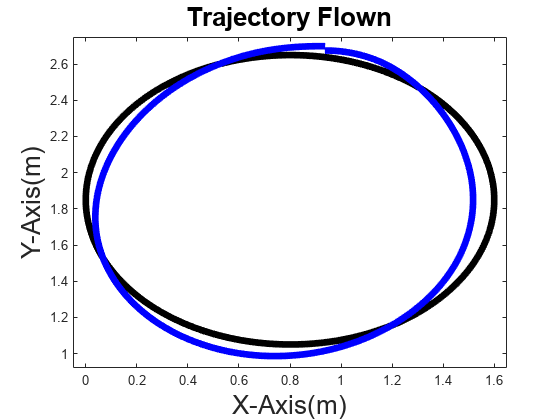



%% Initialize video
%myVideo = VideoWriter('myVideoFile'); %open video file
%myVideo.FrameRate = 100;  %can adjust this, 5 - 10 works well for me
%open(myVideo)

forward = 1;
figure(1)
for i = 1:length(x_cw)
   
    % plot3(x_setpt,y_setpt,z_setpt,'Color','b','linewidth',3)
    % axis([-6.5 6.5 -6.5 6.5 1 4])
    % xlabel('X-Axis','fontsize',12)
    % ylabel('Y-Axis','fontsize',12)
    % zlabel('Z-Axis','fontsize',12)
    % title('Setpoints to follow','fontsize',14)
    plot(x_r,y_r,'Color','black','LineWidth',5);
    hold on
    
    if i*forward > length(x_cw)
        break
    end

    %plot3(x_cw(1:i*forward),y_cw(1:i*forward),z_cw(1:i*forward),'Color','b','linewidth',5)
    plot(x_cw(1:i*forward),y_cw(1:i*forward),'Color','b','linewidth',5)
    %axis([-10 10 -10 10 0 10])
    axis([-0.05 1.65 0.92 2.75])
    xlabel('X-Axis(m)','fontsize',20)
    ylabel('Y-Axis(m)','fontsize',20)
    zlabel('Z-Axis(m)','fontsize',20)
    
    title('Trajectory Flown','fontsize',20)
    %hold on
    
    %method = 'gaussian';
    %window = 120;
    %plot3(smoothdata(x_gpmpc_pose(1:i*forward),method,window),smoothdata(y_gpmpc_pose(1:i*forward),method,window),smoothdata(z_gpmpc_pose(1:i*forward),method,window),'Color','r','linewidth',5)
    %plot3(x_pose,y_pose,z_pose,'linewidth',3)
    %plot(smoothdata(x_mpc_pose,method,window),smoothdata(y_mpc_pose,method,window),'linewidth',3)
    %plot3(smoothdata(x_mpc_pose,method,window),smoothdata(y_mpc_pose,method,window),smoothdata(z_mpc_pose,method,window),':','linewidth',5)
    
    %method = 'gaussian';
    window = 1;
    %plot3(smoothdata(x_mpc_pose(1:i*forward),method,window),smoothdata(y_mpc_pose(1:i*forward),method,window),smoothdata(z_mpc_pose(1:i*forward),method,window),'Color','r','linewidth',5)
    
    hold off
    
    %grid on
    %legend('Setpoint trail left by target','MPC','fontsize',24)
    %legend('Setpoint trail left by target','Cascading Velocity MPC ','fontsize',24)
    drawnow % extra only lol
    %pause(0.001) %Pause and grab frame
    %frame = getframe(gcf); %get frame
    %writeVideo(myVideo, frame);
end

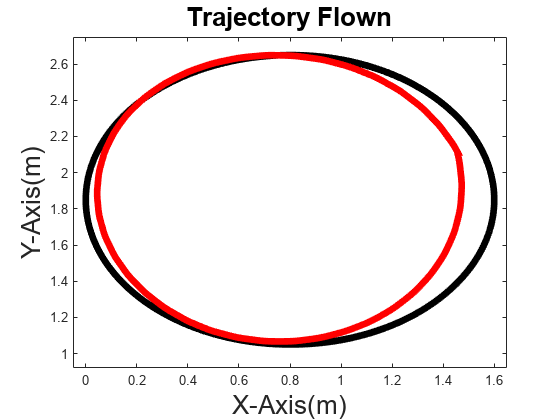

%close(myVideo)


forward = 1;
figure(2)
for i = 1:length(x_ccw)
   
    % plot3(x_setpt,y_setpt,z_setpt,'Color','b','linewidth',3)
    % axis([-6.5 6.5 -6.5 6.5 1 4])
    % xlabel('X-Axis','fontsize',12)
    % ylabel('Y-Axis','fontsize',12)
    % zlabel('Z-Axis','fontsize',12)
    % title('Setpoints to follow','fontsize',14)
    % plot3(x_r,y_r,z_r,'Color','black','LineWidth',5);
    plot(x_r,y_r,'Color','black','LineWidth',5);
    hold on
    
    if i*forward > length(x_ccw)
        break
    end

    %plot3(x_cw(1:i*forward),y_cw(1:i*forward),z_cw(1:i*forward),'Color','b','linewidth',5)
    %plot3(x_ccw(1:i*forward),y_ccw(1:i*forward),z_ccw(1:i*forward),'Color','r','linewidth',5)
    plot(x_ccw(1:i*forward),y_ccw(1:i*forward),'Color','r','linewidth',5)
    %axis([-10 10 -10 10 0 10])
    axis([-0.05 1.65 0.92 2.75])
    xlabel('X-Axis(m)','fontsize',20)
    ylabel('Y-Axis(m)','fontsize',20)
    zlabel('Z-Axis(m)','fontsize',20)
    
    title('Trajectory Flown','fontsize',20)
    %hold on
    
    %method = 'gaussian';
    %window = 120;
    %plot3(smoothdata(x_gpmpc_pose(1:i*forward),method,window),smoothdata(y_gpmpc_pose(1:i*forward),method,window),smoothdata(z_gpmpc_pose(1:i*forward),method,window),'Color','r','linewidth',5)
    %plot3(x_pose,y_pose,z_pose,'linewidth',3)
    %plot(smoothdata(x_mpc_pose,method,window),smoothdata(y_mpc_pose,method,window),'linewidth',3)
    %plot3(smoothdata(x_mpc_pose,method,window),smoothdata(y_mpc_pose,method,window),smoothdata(z_mpc_pose,method,window),':','linewidth',5)
    
    %method = 'gaussian';
    window = 1;
    %plot3(smoothdata(x_mpc_pose(1:i*forward),method,window),smoothdata(y_mpc_pose(1:i*forward),method,window),smoothdata(z_mpc_pose(1:i*forward),method,window),'Color','r','linewidth',5)
    
    hold off
    
    %grid on
    %legend('Setpoint trail left by target','MPC','fontsize',24)
    %legend('Setpoint trail left by target','Cascading Velocity MPC ','fontsize',24)
    drawnow % extra only lol
    %pause(0.001) %Pause and grab frame
    %frame = getframe(gcf); %get frame
    %writeVideo(myVideo, frame);
end

%close(myVideo)




